for k=1:nbus1
    if kb(k)==1
        ms=k;
    end
end
kk=0;
for k=1:ngg
    if k~=ms
        kk=kk+1;
        del(:,kk)=(x(:,k)-x(:,ms));
    end
end

#### First, we define some colours

c11 = [229,245,224]/255;
c13 = [161,217,155]/255;
c12 = [49,163,84]/255;
c21 = [239,237,245]/255;
c23 = [117,107,177]/255;
c22 = [188,189,220]/255;
c_disturbance1 = [222,45,38]/255;
c_disturbance2 = [49,130,189]/255;

#### Plot of machine internal angle vs time

- This code also saves the figure as a PNG file.

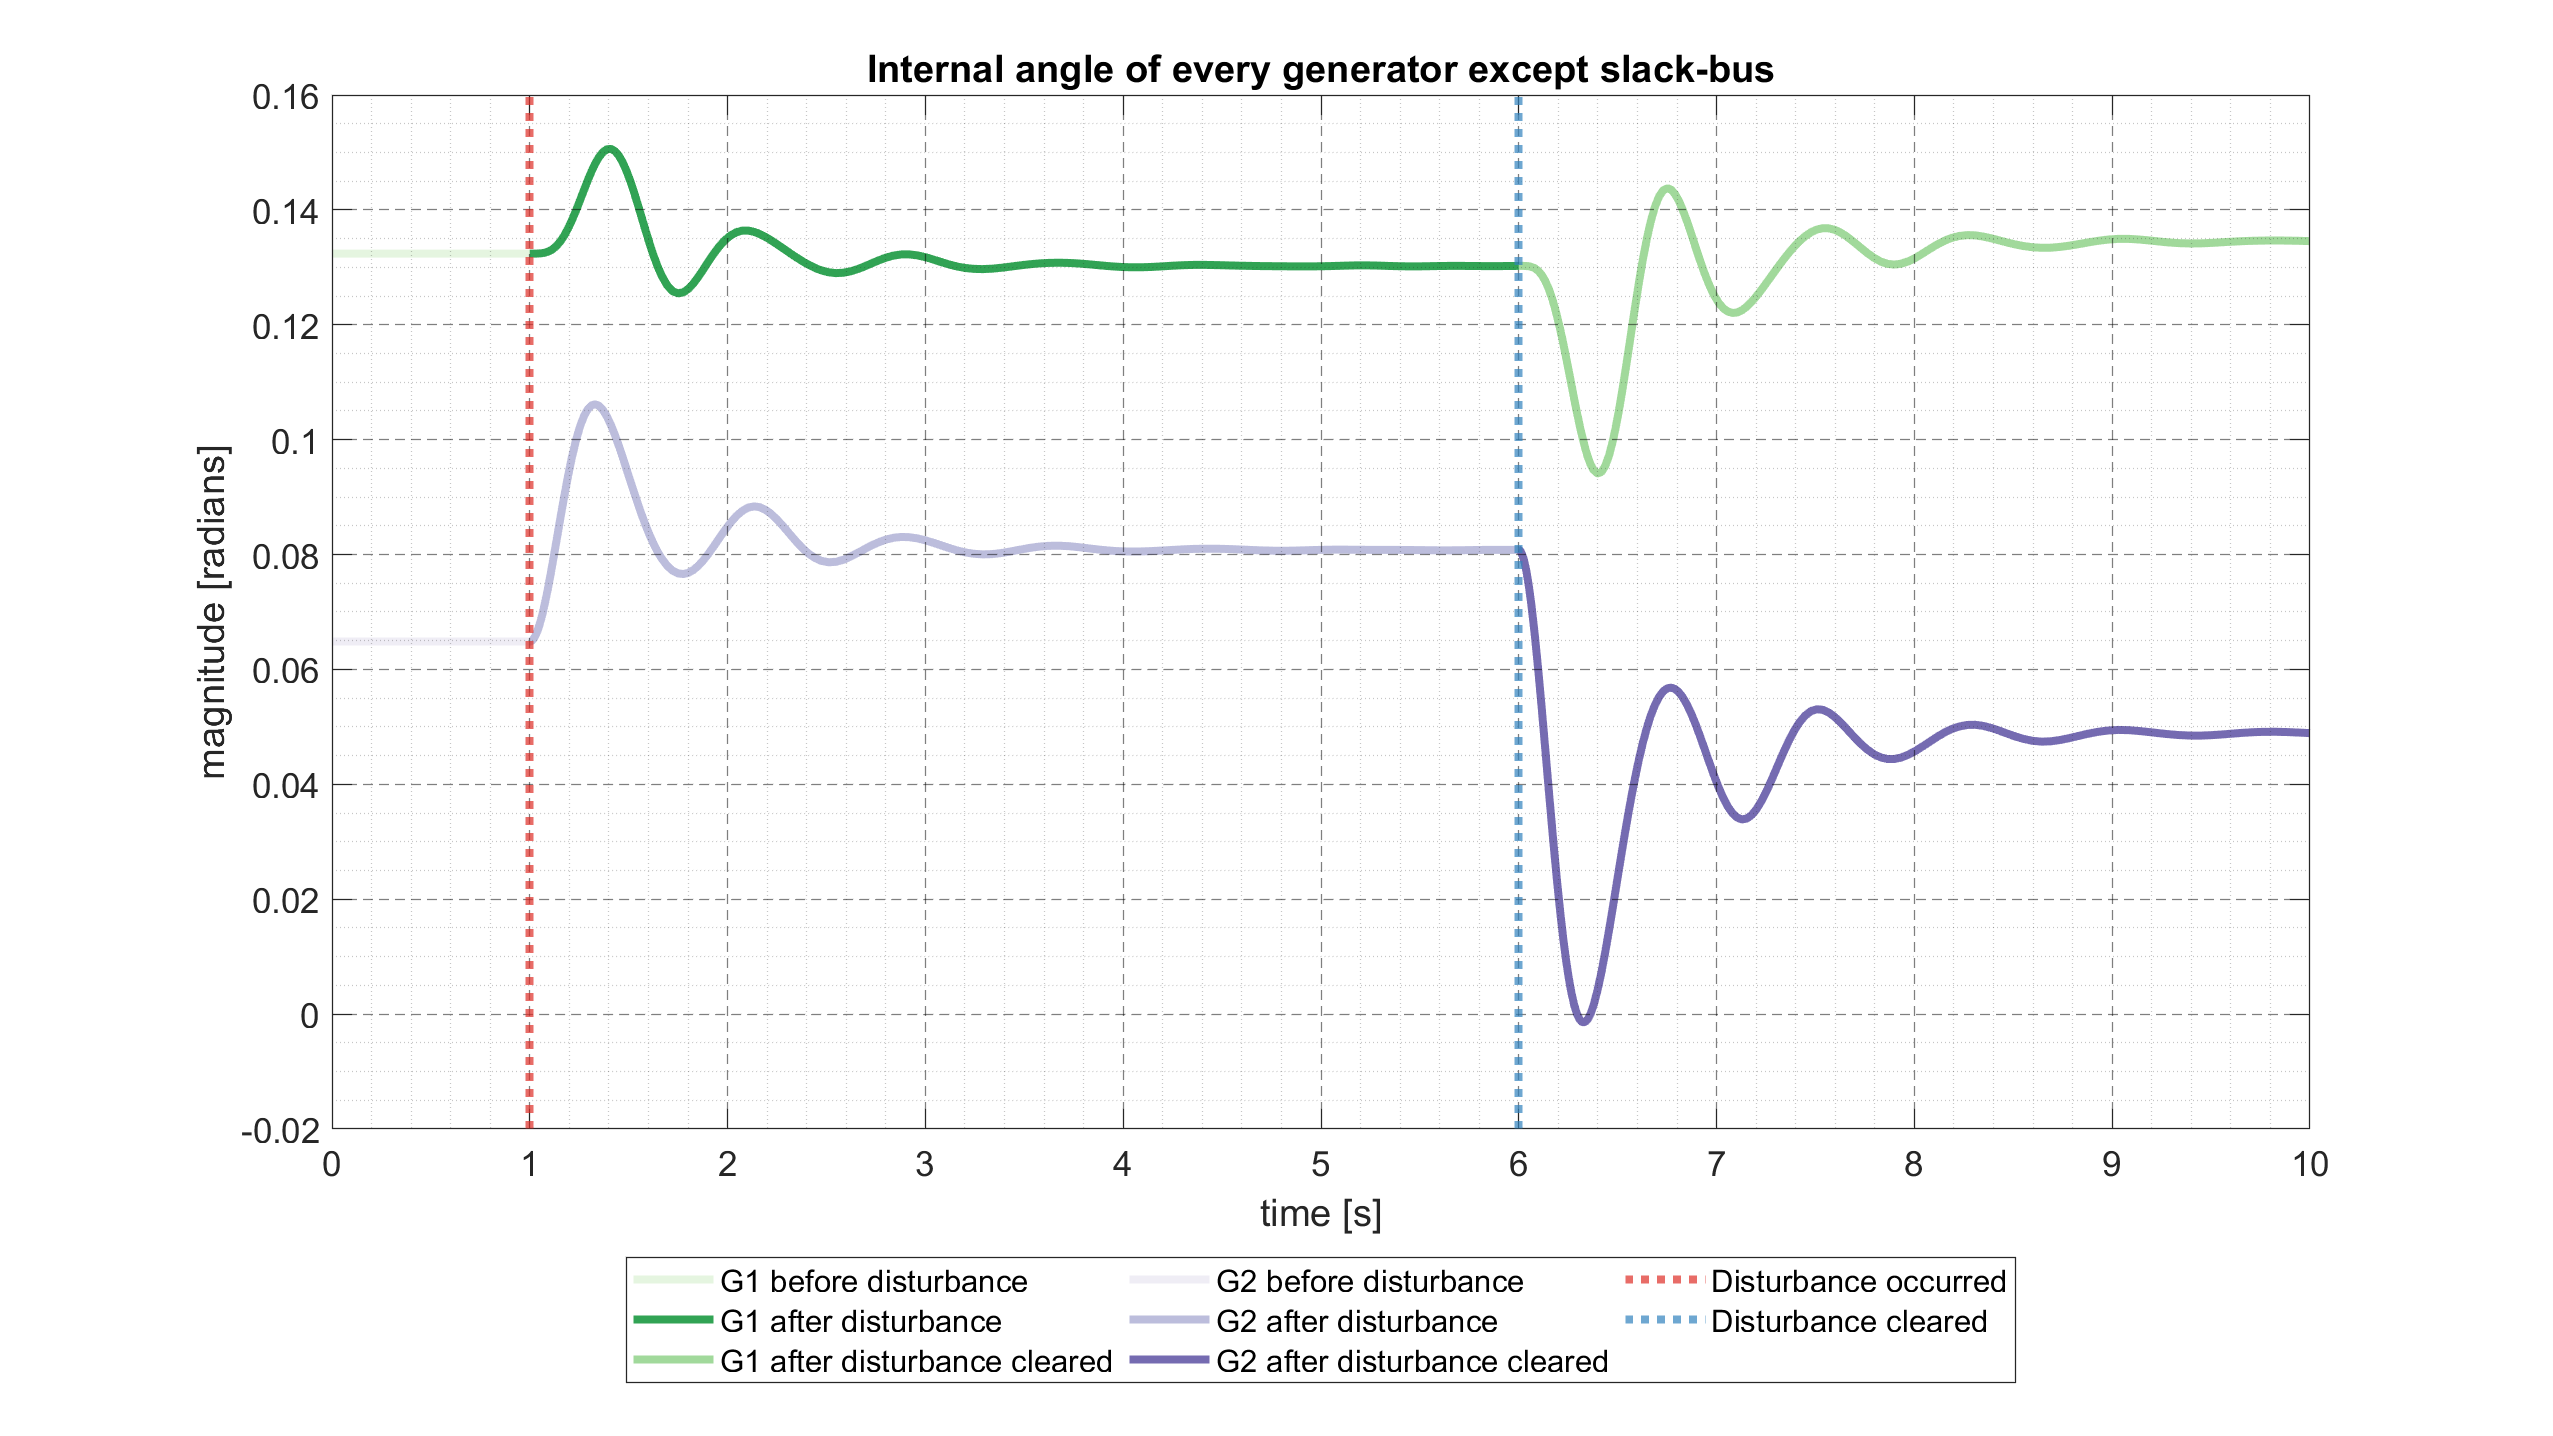

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);
del1=del(1:size(t1,1),:);
del2=del(size(t1,1)+1:size(t1,1)+size(t2,1),:);
del3=del(size(t1,1)+size(t2,1)+1:end,:);
figure(1)
p1=plot(t1,del1(:,1),'color',c11,'LineWidth',3);
hold on;
p2=plot(t2,del2(:,1),'color',c12,'LineWidth',3);
hold on;
p3=plot(t3,del3(:,1),'color',c13,'LineWidth',3);
hold on;
p4=plot(t1,del1(:,2),'color',c21,'LineWidth',3);
hold on;
p5=plot(t2,del2(:,2),'color',c22,'LineWidth',3);
hold on;
p6=plot(t3,del3(:,2),'color',c23,'LineWidth',3);
hold on;
p7=xline(t1(end),'color',c_disturbance1,'LineWidth',3,'LineStyle',':');
hold on;
p8=xline(t2(end),'color',c_disturbance2,'LineWidth',3,'LineStyle',':');

legend({'G2 before disturbance',...
    'G2 after disturbance',...
    'G2 after disturbance cleared',...
    'G3 before disturbance',...
    'G3 after disturbance'...
    'G3 after disturbance cleared',...
    'Disturbance occurred' ...
    'Disturbance cleared'},'Location','southoutside',...
    'Orientation','vertical',...
    'NumColumns',3);
grid on;
grid minor
axP = get(gca,'Position');
set(gca, 'Position', axP)
ax = gca;
ax.GridColor = [0.0000 0.0000 0.000];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
ax.Layer = 'top';
ax.FontSize = 13;
title('Internal angle of every generator except the slack-bus one');
xlabel('time [s]');
ylabel('magnitude [radians]');
filename=['multi_machine_delta_plot'];
saveas(gcf,filename,'png')


fprintf(['Click ' ...
    '<a href=' ...
    '"matlab: winopen(''multi_machine_delta_plot.png'')"' ...
    '>here' ...
    '</a> to view a bigger image.\n'])

Click here to view a bigger image.
